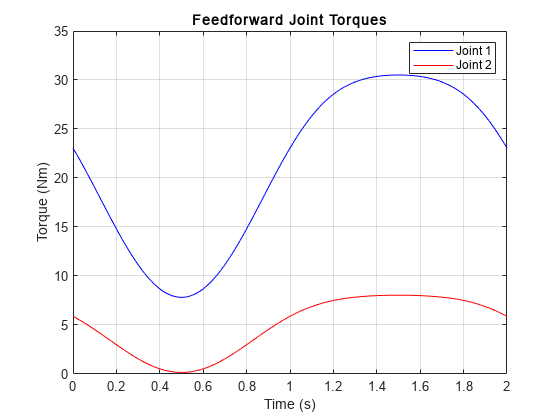

% Feedforward Control for 2-DOF Planar Manipulator
clear all; clc;

% Define manipulator parameters
n = 2; % Number of joints
L1 = 1.0; % Length of link 1 (m)
L2 = 0.8; % Length of link 2 (m)
m1 = 2.0; % Mass of link 1 (kg)
m2 = 1.5; % Mass of link 2 (kg)
g = [0; -9.81; 0]; % Gravity vector (m/s^2)

% Configuration matrices M_{i,i-1} (frames at centers of mass)
M{1} = [1, 0, 0, -0.5; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1];
M{2} = [1, 0, 0, -0.4; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1];
M{3} = [1, 0, 0, -0.4; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1];

% Screw axes A_i (expressed in COM frames)
A{1} = [0; 0; 1; 0; 0.5; 0];
A{2} = [0; 0; 1; 0; 0.4; 0];

% Spatial inertia matrices G_i
I1 = [0, 0, 0; 0, 0, 0; 0, 0, (1/12)*m1*L1^2];
G{1} = [I1, zeros(3); zeros(3), m1*eye(3)];
I2 = [0, 0, 0; 0, 0, 0; 0, 0, (1/12)*m2*L2^2];
G{2} = [I2, zeros(3); zeros(3), m2*eye(3)];

% Animation screw axes
S_1 = [0; 0; 1; 0; 0; 0];
S_2 = [0; 0; 1; 0; -1; 0];

% Animation configuration matrices
M_0_1 = [1, 0, 0, 1; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1];
M_0_2 = [1, 0, 0, 1.8; 0, 1, 0, 0; 0, 0, 1, 0; 0, 0, 0, 1];

% Simulation parameters
tf = 2.0;
N = 500;
dt = tf / N;
t = linspace(0, tf, N+1);

% Desired trajectory (sinusoidal)
theta_d = [0.5 * sin(2 * pi * t / tf); 0.3 * sin(2 * pi * t / tf)];
theta_dot_d = [0.5 * (2 * pi / tf) * cos(2 * pi * t / tf); 0.3 * (2 * pi / tf) * cos(2 * pi * t / tf)];
theta_ddot_d = [-0.5 * (2 * pi / tf)^2 * sin(2 * pi * t / tf); -0.3 * (2 * pi / tf)^2 * sin(2 * pi * t / tf)];

% Initial conditions
theta0 = theta_d(:,1);
theta_dot0 = theta_dot_d(:,1);

% Storage
theta = zeros(n, N+1);
theta_dot = zeros(n, N+1);
theta(:,1) = theta0;
theta_dot(:,1) = theta_dot0;
F_tip = zeros(6,1);
tau_array = zeros(n, N+1);

% Feedforward torque computation
for k = 1:N+1
    tau_array(:,k) = inverse_dynamics(theta_d(:,k), theta_dot_d(:,k), theta_ddot_d(:,k), F_tip, M, A, G, g);
end

% Forward simulation using precomputed torques
for k = 1:N
    tau = tau_array(:,k);
    
    f1 = compute_forward_dynamics(theta(:,k), theta_dot(:,k), tau, F_tip, M, A, G, g);
    f2 = compute_forward_dynamics(theta(:,k) + 0.5*dt*theta_dot(:,k), theta_dot(:,k) + 0.5*dt*f1, tau, F_tip, M, A, G, g);
    f3 = compute_forward_dynamics(theta(:,k) + 0.5*dt*theta_dot(:,k) + 0.25*dt^2*f1, theta_dot(:,k) + 0.5*dt*f2, tau, F_tip, M, A, G, g);
    f4 = compute_forward_dynamics(theta(:,k) + dt*theta_dot(:,k) + 0.5*dt^2*f2, theta_dot(:,k) + dt*f3, tau, F_tip, M, A, G, g);

    theta(:,k+1) = theta(:,k) + dt*theta_dot(:,k) + (dt^2/6)*(f1 + 2*f2 + 2*f3 + f4);
    theta_dot(:,k+1) = theta_dot(:,k) + (dt/6)*(f1 + 2*f2 + 2*f3 + f4);
end

% Plot torques
figure;
plot(t, tau_array(1,:), 'b-', t, tau_array(2,:), 'r-');
title('Feedforward Joint Torques');
xlabel('Time (s)');
ylabel('Torque (Nm)');
legend('Joint 1', 'Joint 2');
grid on;

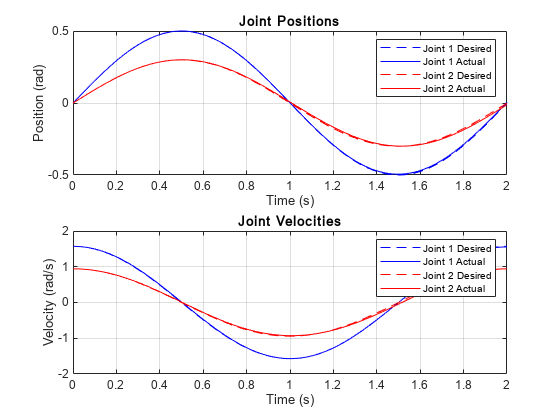


% Plot joint states
figure;
subplot(2,1,1);
plot(t, theta_d(1,:), 'b--', t, theta(1,:), 'b-', t, theta_d(2,:), 'r--', t, theta(2,:), 'r-');
title('Joint Positions');
xlabel('Time (s)');
ylabel('Position (rad)');
legend('Joint 1 Desired', 'Joint 1 Actual', 'Joint 2 Desired', 'Joint 2 Actual');
grid on;

subplot(2,1,2);
plot(t, theta_dot_d(1,:), 'b--', t, theta_dot(1,:), 'b-', t, theta_dot_d(2,:), 'r--', t, theta_dot(2,:), 'r-');
title('Joint Velocities');
xlabel('Time (s)');
ylabel('Velocity (rad/s)');
legend('Joint 1 Desired', 'Joint 1 Actual', 'Joint 2 Desired', 'Joint 2 Actual');
grid on;

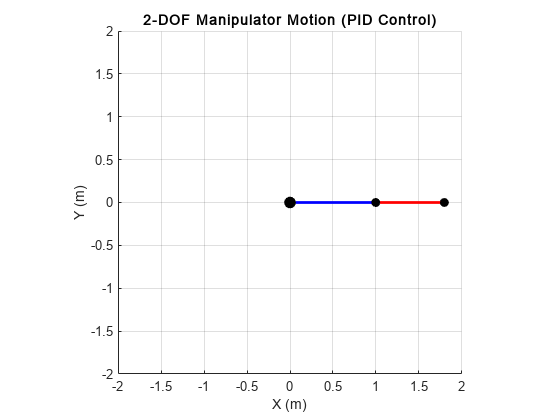

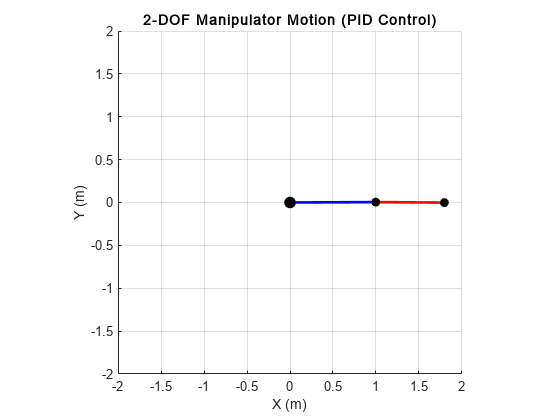


% Animation
figure;
hold on;
grid on;
axis equal;
xlim([-2, 2]);
ylim([-2, 2]);
xlabel('X (m)');
ylabel('Y (m)');
title('2-DOF Manipulator Motion (PID Control)');

for k = 1:N+1
    T0_1 = expm(skew(S_1) * theta(1,k));
    T1 = T0_1 * M_0_1;
    T1_2 = expm(skew(S_2) * theta(2,k));
    T2 = T0_1 * T1_2 * M_0_2;
    
    p0 = [0; 0; 0];
    p1 = T1(1:3,4);
    p2 = T2(1:3,4);
    
    cla;
    plot([p0(1), p1(1)], [p0(2), p1(2)], 'b-', 'LineWidth', 2);
    plot([p1(1), p2(1)], [p1(2), p2(2)], 'r-', 'LineWidth', 2);
    plot(p0(1), p0(2), 'ko', 'MarkerSize', 8, 'MarkerFaceColor', 'k');
    plot(p1(1), p1(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'k');
    plot(p2(1), p2(2), 'ko', 'MarkerSize', 6, 'MarkerFaceColor', 'k');
    
    drawnow;
    pause(0.01);
end


% Include dynamics functions (same as original)


function J = compute_jacobian(theta, M, A)
    n = length(theta);
    J_s = zeros(6,n);
    M_0_i = cell(n,1);
    T = eye(4);
    for i = 1:n
        T = T * inv(M{i});
        M_0_i{i} = T;
    end
    S = cell(n,1);
    for i = 1:n
        S{i} = adjoint(M_0_i{i}) * A{i};
    end
    T = eye(4);
    for i = 1:n
        J_s(:,i) = adjoint(T) * S{i};
        T = T * expm(skew(S{i}) * theta(i));
    end
    J = adjoint(inv(T)) * J_s;
end

function tau = inverse_dynamics(theta, theta_dot, theta_ddot, F_tip, M, A, G, g)
    n = length(theta);
    nu = cell(n+1,1); 
    nu_dot = cell(n+1,1); 
    F = cell(n+1,1);
    tau = zeros(n,1);
    nu{1} = zeros(6,1); nu_dot{1} = [zeros(3,1); -g]; F{n+1} = F_tip;
    for i = 1:n
        T = expm(-skew(A{i}) * theta(i)) * M{i};
        Ad = adjoint(T);
        nu{i+1} = A{i} * theta_dot(i) + Ad * nu{i};
        nu_dot{i+1} = A{i} * theta_ddot(i) + Ad * nu_dot{i} + ad_matrix(nu{i+1}) * A{i} * theta_dot(i);
    end
    for i = n:-1:1
        if i == n, T = M{n+1}; else, T = expm(-skew(A{i+1}) * theta(i+1)) * M{i+1}; end
        Ad_T = adjoint(T)';
        F{i} = Ad_T * F{i+1} + G{i} * nu_dot{i+1} - ad_matrix(nu{i+1})' * (G{i} * nu{i+1});
        tau(i) = F{i}' * A{i};
    end
end

function theta_ddot = compute_forward_dynamics(theta, theta_dot, tau, F_tip, M, A, G, g)
    n = length(theta);
    h = inverse_dynamics(theta, theta_dot, zeros(n,1), zeros(6,1), M, A, G, g);
    M_theta = zeros(n,n);
    for i = 1:n
        ei = zeros(n,1); ei(i) = 1;
        M_theta(:,i) = inverse_dynamics(theta, zeros(n,1), ei, zeros(6,1), M, A, G, zeros(3,1));
    end
    J = compute_jacobian(theta, M, A);
    theta_ddot = M_theta \ (tau - h - J' * F_tip);
end

function S = skew(v)
    if length(v) == 3
        S = [0 -v(3) v(2); v(3) 0 -v(1); -v(2) v(1) 0];
    elseif length(v) == 6
        omega = v(1:3); v_linear = v(4:6);
        S = [skew(omega), v_linear; 0 0 0 0];
    else
        error('Invalid size');
    end
end

function Ad = adjoint(T)
    R = T(1:3,1:3); p = T(1:3,4);
    Ad = [R zeros(3); skew(p)*R R];
end

function ad = ad_matrix(V)
    w = V(1:3); v = V(4:6);
    ad = [skew(w), zeros(3); skew(v), skew(w)];
end
